# Brison equation ( factor analysis for securities)

Assume a portfolio with 'n' different assets, $r_{\mathrm{ip}}$ and $w_{\mathrm{ip}}$ are the return and weights of the asset 'i',  $r_{\mathrm{ib}}$ and $w_{\mathrm{ib}}$ are the return and weights of the benchmark asset, the "alpha/total return" is defined as:


$$\mathrm{TR}=r_p -r_b =\sum_{i=1}^n w_{\mathrm{ip}} r_{\mathrm{ip}} -\sum_{i=1}^n w_{\mathrm{ib}} r_{\mathrm{ib}}$$


where the arrtribution of  the asset portfolio（Asset return） is measure by:


$$\mathrm{AR}=\sum_{i=1}^n \left(w_{\mathrm{ip}} -w_{\mathrm{ib}} \right)r_{\mathrm{ib}}$$


the single asset return is measure by:


$$\mathrm{SR}=\sum_{i=1}^n \left(r_{\mathrm{ip}} -r_{\mathrm{ib}} \right)w_{\mathrm{ib}} \;$$


the mutual info is measure by:


$$\mathrm{IR}=\sum_{i=1}^n \left(r_{\mathrm{ip}} -r_{\mathrm{ib}} \right)\left(w_{\mathrm{ip}} -w_{\mathrm{ib}} \right)\;$$


Accordingly, its easy to prove:


$$\mathrm{TR}=\mathrm{AR}+\mathrm{SR}+\mathrm{IR}$$


Created in 2020-12-19 by XuSUN.

## 0.Initialization

% Close all the windows,clear the workspace and the command window
clc;
clear all;
close all;


## 1.Load / Create the data

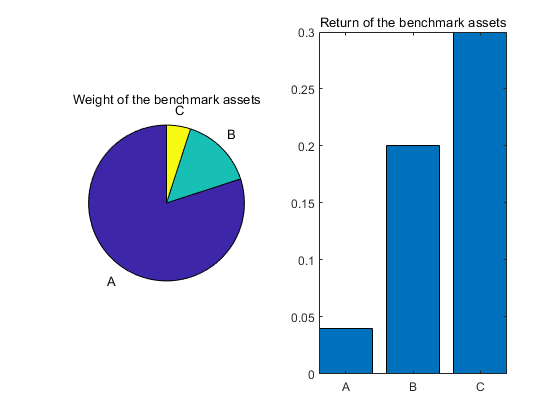

% Parameters of the bench mark assets 
w_ib = [0.8, 0.15, 0.05];
r_ib = [0.04, 0.2, 0.3];

figure;labels = {'A','B','C'};
subplot(1,2,1),pie(w_ib,labels),title('Weight of the benchmark assets');
subplot(1,2,2),bar(r_ib);title('Return of the benchmark assets');set(gca,'XTicklabel',labels);axis tight;

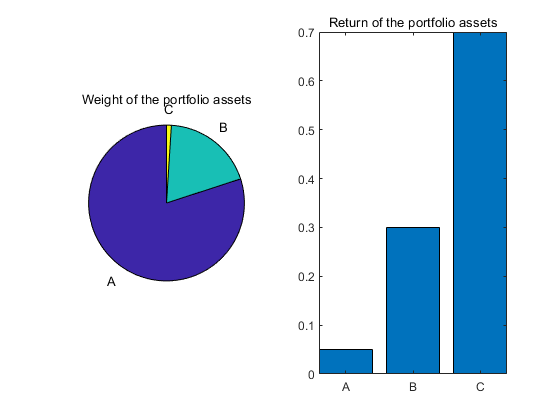

% Parameters of the asset portforlio
w_ip = [0.8, 0.19, 0.01];
r_ip = [0.05,0.3, 0.7];

figure;labels = {'A','B','C'};
subplot(1,2,1),pie(w_ip,labels),title('Weight of the portfolio assets');
subplot(1,2,2),bar(r_ip);title('Return of the portfolio assets');set(gca,'XTicklabel',labels);axis tight;

## 2.Brison model calculation


% Return of the Bench mark assets
R_b = w_ib.*r_ib;

% Total return of the asset portforlio
R = w_ip.*r_ip;

% TR
TR = sum(R - R_b);

% AR, Asset return,according to Brison model def:
AR = sum((w_ip-w_ib).*r_ib);

% SR,single asset return
SR = sum((r_ip-r_ib).*w_ib);

% IR, mutual info
IR = sum((r_ip-r_ib).*(w_ip-w_ib));


## 3.Result Plot

ResultsTab = array2table([TR,AR,SR,IR],"VariableNames",{'TR','AR','SR','IR'});
format shortG;
fprintf('Excess return, TR:    %.4f\n',TR);

Excess return, TR:    0.0270


fprintf('(1)Asset return(AR):    %.4f\n',AR);

(1)Asset return(AR):    -0.0040


fprintf('(2)Single asset return(SR):    %.4f\n',SR);

(2)Single asset return(SR):    0.0430


fprintf('(3)Mutual info(IR):    %.4f\n',IR);

(3)Mutual info(IR):    -0.0120



format shortG;
fprintf('超额收益, TR:    %.4f\n',TR);

超额收益, TR:    0.0270


fprintf('(1)资产配置贡献(AR):    %.4f\n',AR);

(1)资产配置贡献(AR):    -0.0040


fprintf('(2)个股/个类资产选择贡献(SR):    %.4f\n',SR);

(2)个股/个类资产选择贡献(SR):    0.0430


fprintf('(3)交互贡献(IR):    %.4f\n',IR);

(3)交互贡献(IR):    -0.0120
